**Parameters**

% M matrix -> it's symmetric
m1 = 96.8;
m2 = -3.57;
m3 = -3.57;
m4 = 0.258;

% C matrix
c1 = 0;
c2 = -50.8;
c3 = 0.436;
c4 = 2.20;

% K0 matrix
k11 = -901.0;
k12 = 35.17;
k13 = 35.17;
k14 = -12.03;

% K2 matrix
k21 = 0;
k22 = -87.06;
k23 = 0;
k24 = 3.50;

V = 5;

**State Space representation**

a1 = k11+k21*V^2;
a2 = k12+k22*V^2;
a3 = k13+k23*V^2;
a4 = k14+k24*V^2;

A1 = m2/(m2*m3-m1*m4);
A2 = m4/m2;
A3 = m1/m2;

A = [
    0                                     0                             1                               0;
    0                                     0                             0                               1;
    A1*A2*a1-A1*a3                     A1*A2*a2-A1*a4                 A1*A2*c1*V-A1*c3*V                  A1*A2*c2*V-A1*c4*V;
    -A1*A2*A3*a1+A1*A3*a3-a1/m2     -A1*A2*A3*a2+A1*A3*a4-a2/m2     -A1*A2*A3*c1*V+A1*A3*c3*V-c1*V/m2     -A1*A2*A3*c2*V+A1*A3*c4*V-c2*V/m2;
];

B = [
    0;
    0;
    A1;
    -A3*A1
];

C = [1 0 0 0];
D = 0;

sys_ss = ss(A, B,C,D)

sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3    8.741    23.14  -0.6364    2.147
   x4   -15.36    27.72   -17.26   -12.92
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.2919
   x4   7.915
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



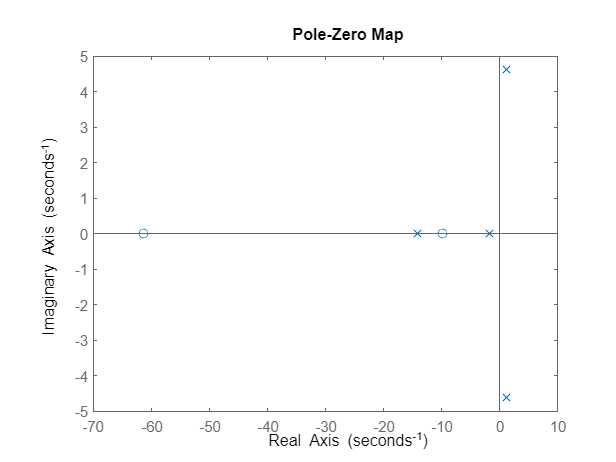

pzmap(sys_ss)

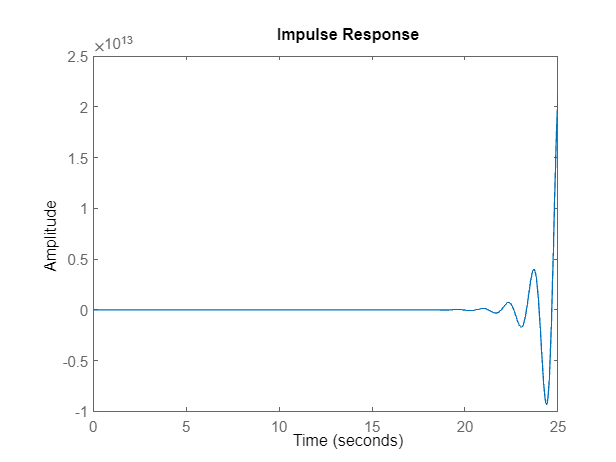

impulse(sys_ss)

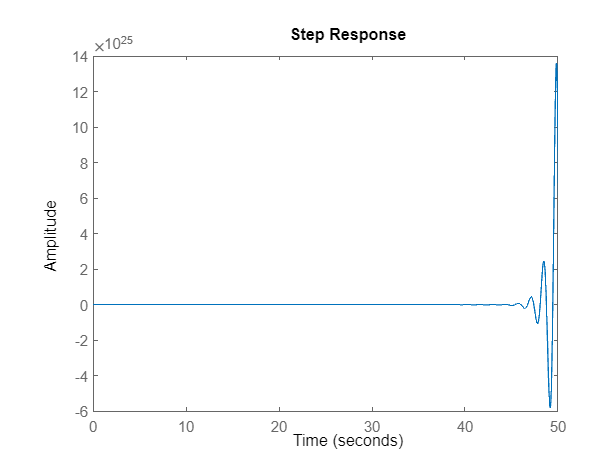

step(sys_ss)

pole(sys_ss)

ans =    1.2516 + 4.6149i
   1.2516 - 4.6149i
  -1.8387 + 0.0000i
 -14.2220 + 0.0000i


**Stability Analysis**

Q = eye(length(A));
P = lyap(A,Q);

if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is not stable.


**Controllability and Observability**

obsy = obsv(sys_ss.A, sys_ss.C);
conty = ctrb(sys_ss.A, sys_ss.B);

if rank(obsy) == length(sys_ss.A)
    disp('The system is controllable.')
else
    disp('The system is not controllable.')
end

The system is controllable.


if rank(conty) == length(sys_ss.A)
    disp('The system is observable.')
else
    disp('The system is not observable.')
end

The system is observable.


if rank(obsy) == length(A) && rank(conty) == length(A)
    disp('This realization is minimal.')
else
    disp('This realization is not minimal.')
end

This realization is minimal.


## **Designing State FB Controller using LQR + Observer**

pole(sys_ss)

ans =    1.2516 + 4.6149i
   1.2516 - 4.6149i
  -1.8387 + 0.0000i
 -14.2220 + 0.0000i


**LQR**

Q = [
    1/0.01  0   0   0;
    0   1/0.04  0   0;
    0   0   0   0;
    0   0   0   0;
];
R = 1/4;

[K, S,P] = lqr(sys_ss, Q, R)

K =    25.8018   20.1905    4.4580    1.4741


S =    35.4297    6.9020    4.9138    0.6337
    6.9020    9.6478    0.9392    0.6031
    4.9138    0.9392    1.0262    0.1030
    0.6337    0.6031    0.1030    0.0428


P =   -3.9217 + 5.9548i
  -3.9217 - 5.9548i
  -5.3538 + 0.0000i
 -13.3297 + 0.0000i


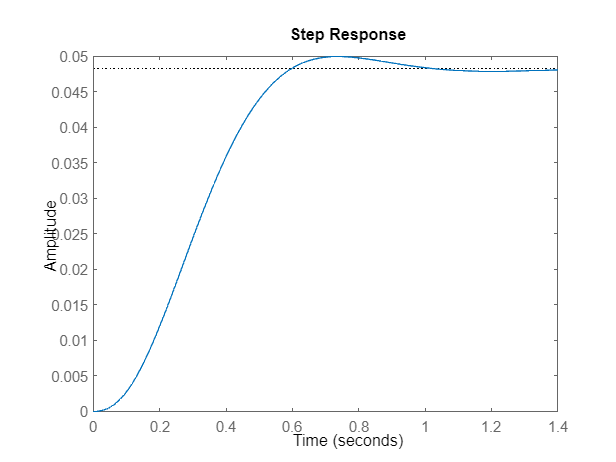

sys_lqr = ss(A-B*K, B,C,D);

step(sys_lqr)

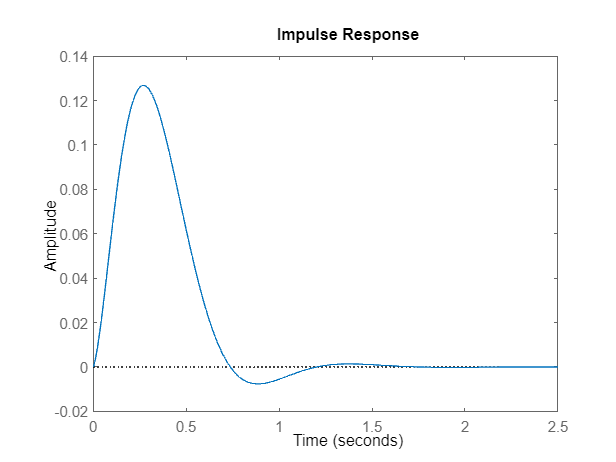

impulse(sys_lqr)

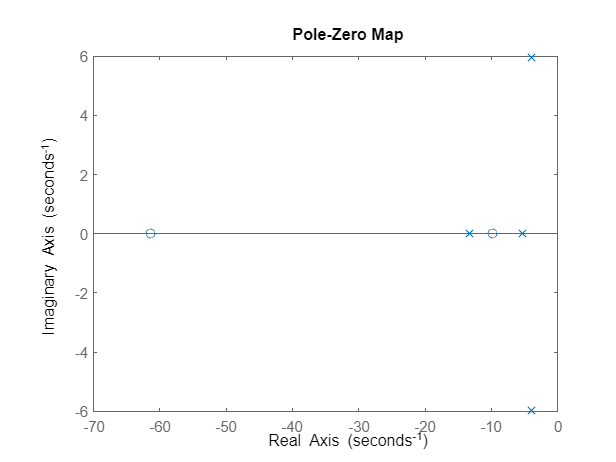

pzmap(sys_lqr)

pole(sys_lqr)

ans =  -13.3297 + 0.0000i
  -3.9217 + 5.9548i
  -3.9217 - 5.9548i
  -5.3538 + 0.0000i


**Observer**

% observer_poles -> roughly 2 times faster than the fastest system pole after using LQR State FB
observer_poles = [-26, -26, -26, -26];
L_t = acker(A', C', observer_poles);
L = L_t'

L = 1.0e+03 *

    0.0904
    1.4253
    2.8210
   -0.4768


A_obs = A-L*C

A_obs = 1.0e+03 *

   -0.0904         0    0.0010         0
   -1.4253         0         0    0.0010
   -2.8123    0.0231   -0.0006    0.0021
    0.4614    0.0277   -0.0173   -0.0129


B_obs = [B L] % input is [u Y]'

B_obs = 1.0e+03 *

         0    0.0904
         0    1.4253
    0.0003    2.8210
    0.0079   -0.4768


C_obs = eye(length(A_obs)) % since we want all the states

C_obs =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_obs = zeros(size(B_obs))

D_obs =      0     0
     0     0
     0     0
     0     0
